# 適応アルゴリズム比較

## 基本

fleng     = 10;       %タップ数
ssize     = 0.05;    %ステップサイズ
fsize     = 200;
NI        = 10;

## LMSフィルタの設計

lmsfilt = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',ssize);

## NLMSフィルタの設計

nlmsfilt = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

## APフィルタの設計

po = 5;    %次元数
apfilt = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',0.05 ,'ProjectionOrder', po);

## ノイズの生成

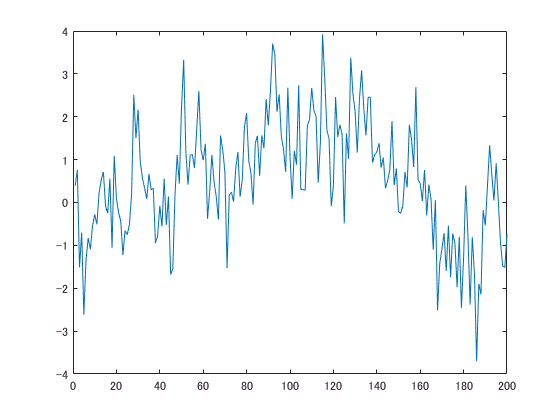

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
pinkn = Hp();
plot(pinkn);

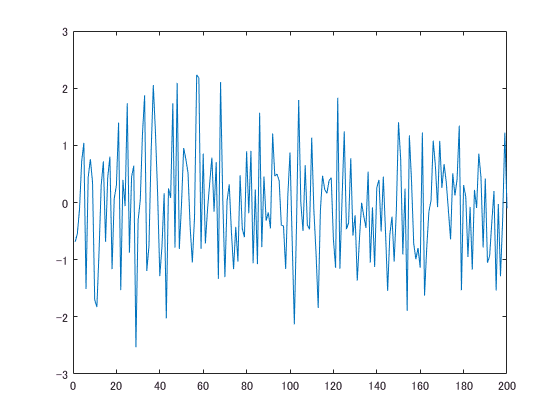

Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
whiten = Hw();
plot(whiten);


firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

TS = dsp.TimeScope('TimeSpan',1.5*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',50*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err','fil'});

sinewave = dsp.SineWave('Frequency',0.01, ...
    'SampleRate',1,'SamplesPerFrame',fsize);

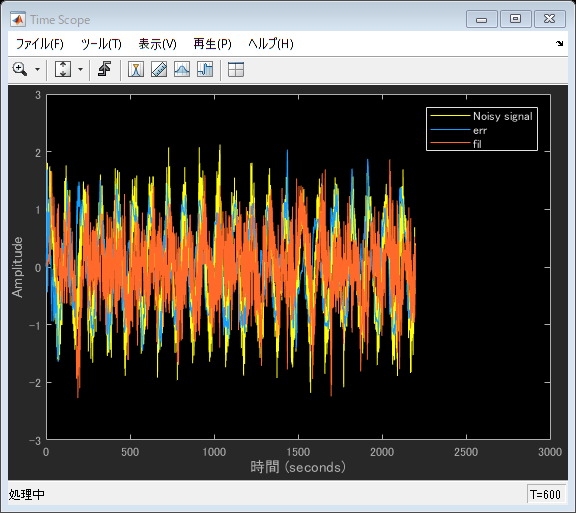

for i = 0:NI
    d = Hw();
    x = firfilt(d)+sinewave();
    [y,e] = apfilt(d,x);
    TS([x,e,y]);
end